## House Keeping

clear all
close all
clc
s = tf('s');

## Model

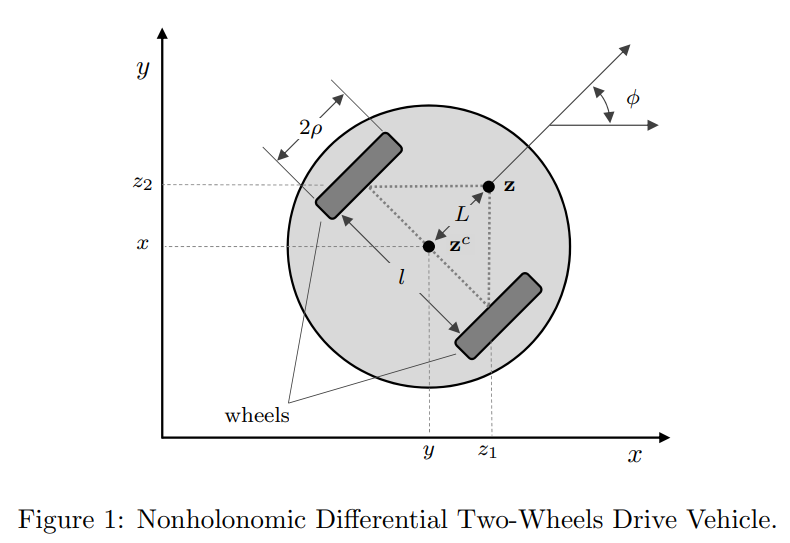

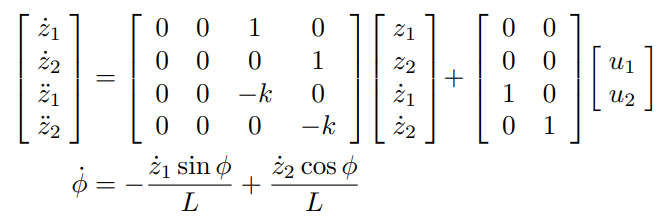

k = 1;      % Arbitrary positive constant

Input-Output Linearized Model

A = [0 0 1 0;
     0 0 0 1;
     0 0 -k 0;
     0 0 0 -k];
B = [0 0;
     0 0;
     1 0;
     0 1];
C = eye(size(B,2),size(B,1));
D = zeros(size(C,1),size(B,2));
sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2  x3  x4
   x1   0   0   1   0
   x2   0   0   0   1
   x3   0   0  -1   0
   x4   0   0   0  -1
 
  B = 
       u1  u2
   x1   0   0
   x2   0   0
   x3   1   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



State Space Description

size(sys)

State-space model with 2 outputs, 2 inputs, and 4 states.


Transfer Function of System

G = C*inv(s*eye(size(A)) - A)*B + D

G =
 
  From input 1 to output...
                1
   1:  -------------------
       s^2 + s - 1.935e-16
 
   2:  0
 
  From input 2 to output...
   1:  0
 
                1
   2:  -------------------
       s^2 + s - 2.614e-17
 
Continuous-time transfer function.



G = [1/(s^2 + s - 1.935e-16) 0;
     0 1/(s^2 + s - 2.614e-17)];

Can treat as 2 SISO systems since it's diagonal matrix of transfer functions

Check Bode of SISO system first to see if smoothing is required

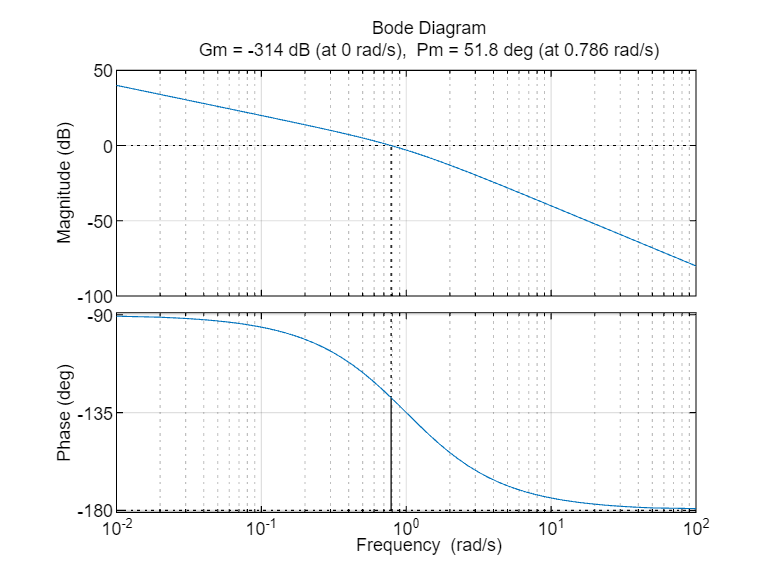

% Plot settings
p = bodeoptions;
p.PhaseMatching = 'on';
p.Grid = 'on';
margin(G(1,1),p)

We can see that there are no resonance peaks, therefore smoothing (additional poles to make the system realizable) is not required

- Block diagram required

- Weights are required (Make arbitrary for now)

- Generalized Plant required

- nmeas and ncont required

- *musyn()*

Uncertainty Plant

m = ureal('mass',20,'Percentage',5) % mass = 20 w/ 5% uncertainty

m =   Uncertain real parameter "mass" with nominal value 20 and variability [-5,5]%.


G_unc = tf(1,[m,0,0]);
Gvec_unc = usample(G_unc,100);
[P_unc,info_unc] = ucover(Gvec_unc,G_unc.NominalValue,4);
Wt = info_unc.W1; % Weight Extraction

Mu Synthesis Controller Gains

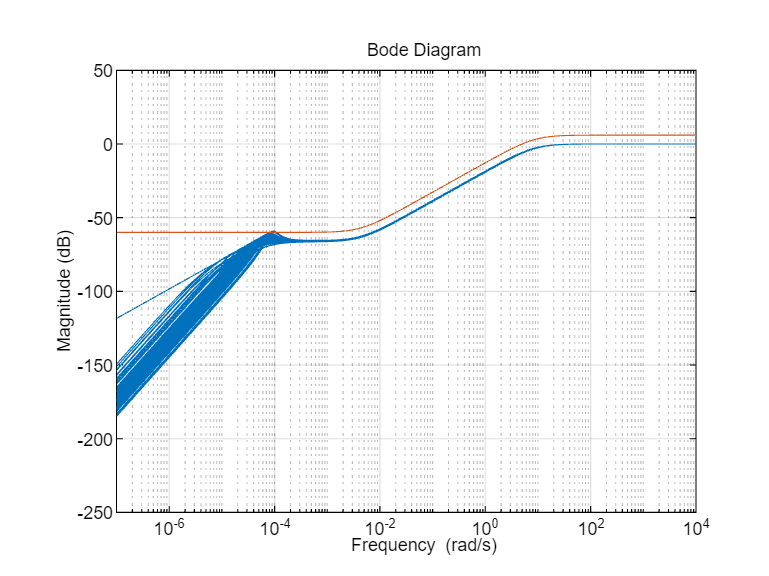

wh = 10;
wl = 0;
w_try = wh;
w_new = (wh+wl)/2;
iter = 1;
while(abs(w_new-w_try)>1e-2)
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K,CL,GAM(iter)] = mixsyn(G_unc,Wp,[],Wt);
    S = 1-feedback(G_unc*K,1);
    perfmarg = robgain(Wp*S,1);
    mu(iter) = 1/perfmarg.UpperBound;
    Smult = 1-feedback(P_unc*K,1);
    perfmarg = robgain(Wp*Smult,1);
    mumult(iter) = 1/perfmarg.UpperBound;
    if mu(iter)<1
        wl = w_try;
    else
        wh = w_try;
    end
    w_new = (wh+wl)/2;
    iter = iter + 1;
end
S = 1/(1+G_unc*K);
Svec = usample(S,100);
bodemag(Svec,1/Wp,p)

We use *mixsyn() *instead of *musyn()* because *mixsyn()* is faster. It is also easier to build the uncertainty plant than to build the generalized plant for *musyn(). *

Now that we have the skeleton, let's do it from -100% to 100% uncertainty.

for mass_unc = [1:100]
m = ureal('mass',20,'Percentage',mass_unc) % mass = 20 w/ 5% uncertainty
G_unc = tf(1,[m,0,0]);
Gvec_unc = usample(G_unc,100);
[P_unc,info_unc] = ucover(Gvec_unc,G_unc.NominalValue,4);
Wt = info_unc.W1; % Weight Extraction
wh = 10;
wl = 0;
w_try = wh;
w_new = (wh+wl)/2;
iter = 1;
while(abs(w_new-w_try)>1e-2)
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K(mass_unc),CL,GAM(iter)] = mixsyn(G_unc,Wp,[],Wt);
    S = 1-feedback(G_unc*K(mass_unc),1);
    perfmarg = robgain(Wp*S,1);
    mu(iter) = 1/perfmarg.UpperBound;
    Smult = 1-feedback(P_unc*K(mass_unc),1);
    perfmarg = robgain(Wp*Smult,1);
    mumult(iter) = 1/perfmarg.UpperBound;
    if mu(iter)<1
        wl = w_try;
    else
        wh = w_try;
    end
    w_new = (wh+wl)/2;
    iter = iter + 1;
end
end

m =   Uncertain real parameter "mass" with nominal value 20 and variability [-1,1]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-2,2]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-3,3]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-4,4]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-5,5]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-6,6]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-7,7]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-8,8]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-9,9]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-10,10]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-11,11]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-12,12]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-13,13]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-14,14]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-15,15]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-16,16]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-17,17]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-18,18]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-19,19]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-20,20]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-21,21]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-22,22]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-23,23]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-24,24]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-25,25]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-26,26]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-27,27]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-28,28]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-29,29]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-30,30]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-31,31]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-32,32]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-33,33]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-34,34]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-35,35]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-36,36]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-37,37]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-38,38]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-39,39]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-40,40]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-41,41]%.


m =   Uncertain real parameter "mass" with nominal value 20 and variability [-42,42]%.
